### Compression Testing

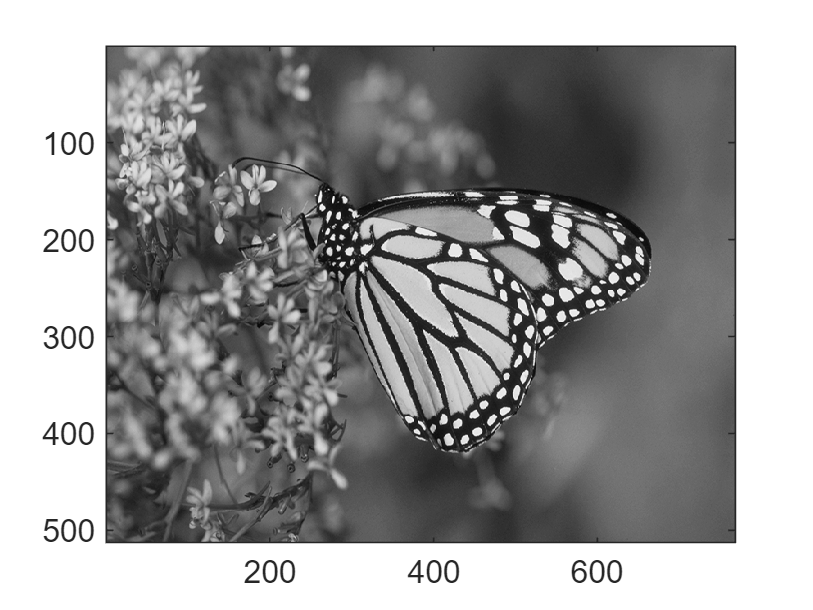

clear
hold off
clc

images = {imread('carpet.bmp'), imread('houses.bmp'), imread('monarch.bmp'), imread('rover.png'), imread('noise.png'), imread('cat.png')};
for i = 1:length(images)
    images{i} = im2gray(images{i});
    images{i} = double(images{i});
    [n,m] = size(images{i});
    if mod(n,8)~=0 || mod(m,8)~=0
        images{i} = images{i}(1:n-mod(n,8),1:m-mod(m,8));
    end
end

imagesc(images{3})
colormap("gray")

% TEST THE THINGIES
methods = {@fft_compress, @svd_compress, @dct_compress};

N = 3

N = 3

im_size = numel(images{N});

disp(min(images{N}, [], 'all'))

    17



disp(max(images{N}, [], 'all'))

   245




mses = {[],[],[]};
times = {[],[],[]};
ratio = {[],[],[]};
ssims = {[],[],[]};
psnrs = {[],[],[]};
range = 5:100;

for j = 1:3
    for k = 5:100
        [mse, time, count, output] = compression_test(methods{j}, images{N}, k);
        
        ssims{j} = [ssims{j}, ssim(output, uint8(images{N}))];
        mses{j} = [mses{j}, mse/length(output)];
        times{j} = [times{j}, time];
        ratio{j} = [ratio{j}, im_size/count];
        psnrs{j} = [psnrs{j}, 20*log10(double(255.)) - 10*log10(mse)];
    end
end

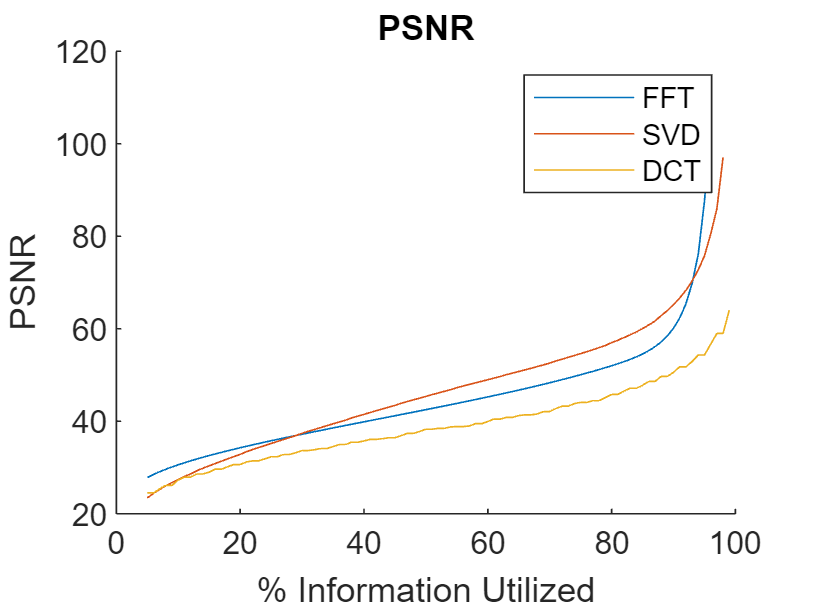

figure;
hold on
plot(range, psnrs{1})
plot(range, psnrs{2})
plot(range, psnrs{3})
%yscale('log')
legend(["FFT", "SVD", "DCT"])
title("PSNR")
xlabel("% Information Utilized")
ylabel("PSNR")
hold off

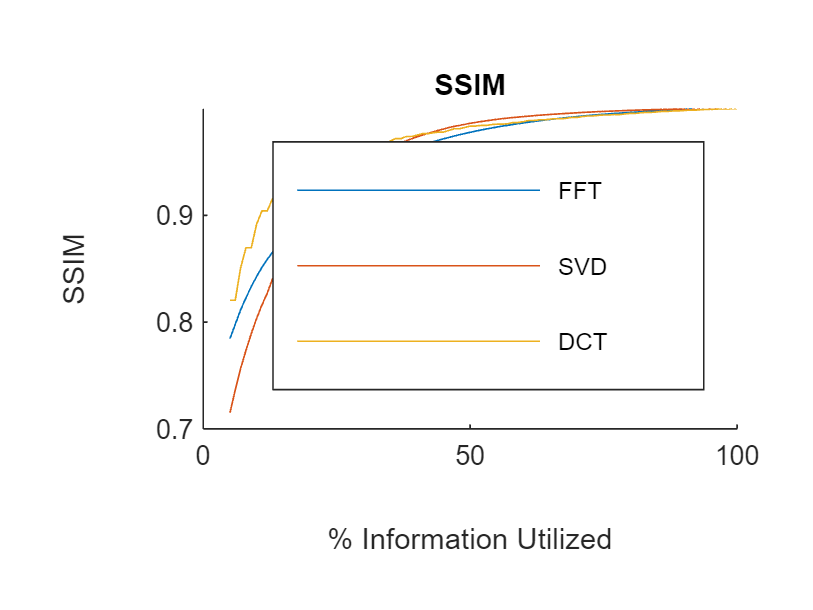

figure;
hold on
plot(range, ssims{1})
plot(range, ssims{2})
plot(range, ssims{3})
%yscale('log')
legend(["FFT", "SVD", "DCT"])
title("SSIM")
xlabel("% Information Utilized")
ylabel("SSIM")
hold off

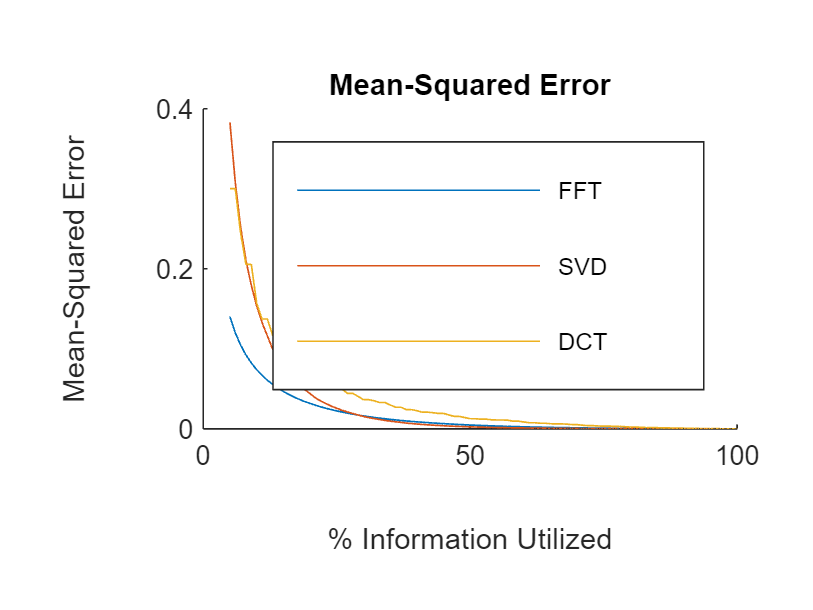

figure;
hold on
plot(range, mses{1})
plot(range, mses{2})
plot(range, mses{3})
%yscale('log')
legend(["FFT", "SVD", "DCT"])
title("Mean-Squared Error")
xlabel("% Information Utilized")
ylabel("Mean-Squared Error")
hold off

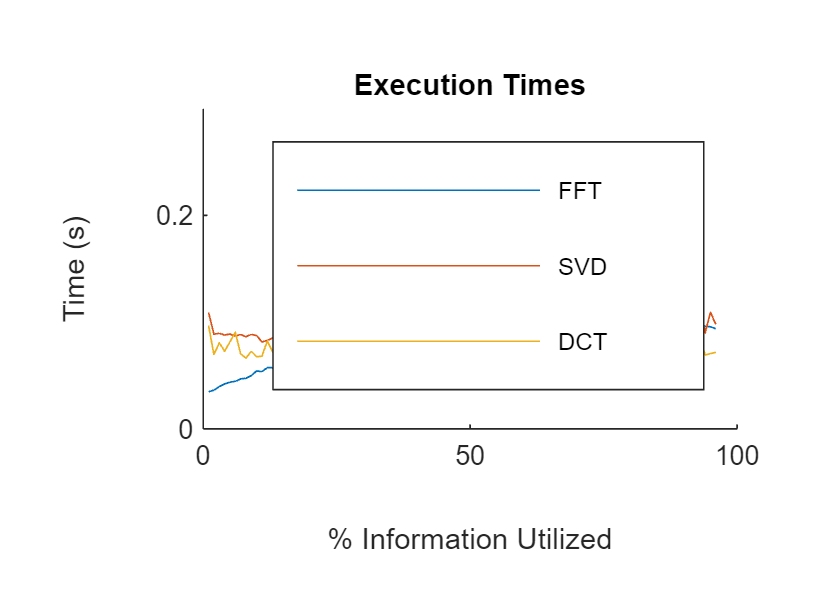

figure;
hold on
plot(times{1})
plot(times{2})
plot(times{3})
legend(["FFT", "SVD", "DCT"])
title("Execution Times")
xlabel("% Information Utilized")
ylabel("Time (s)")
hold off

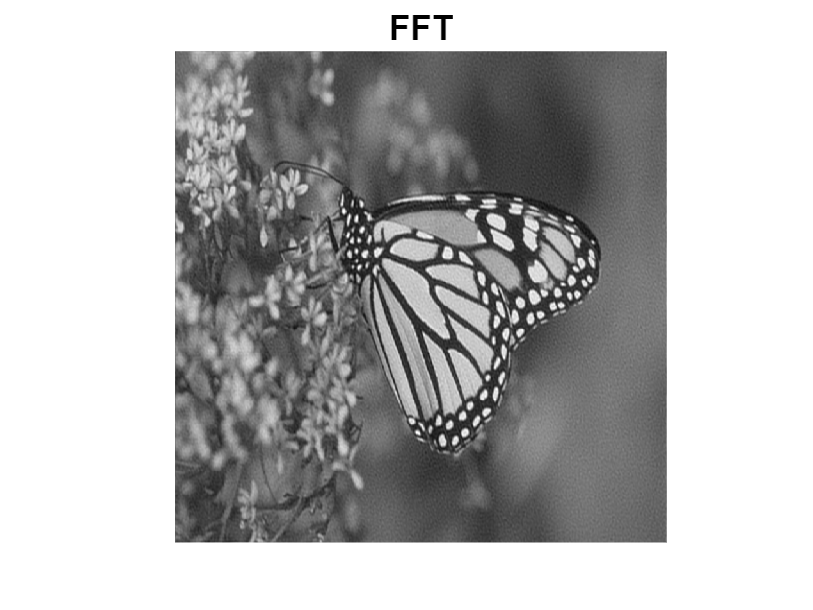

[fft_img,~] = fft_compress(images{N}, 10);  %20
[svd_img,~] = svd_compress(images{N}, 10);  %10
[dct_img,~] = dct_compress(images{N}, 10);  %41
% All values set for 5:1 compression ratio.

%tiledlayout(1,3,'Padding', 'compact', 'TileSpacing','compact');
%nexttile
imagesc(fft_img)
colormap("gray")
axis('off')
title("FFT")
pbaspect([1 1 1])
clim([0,255])

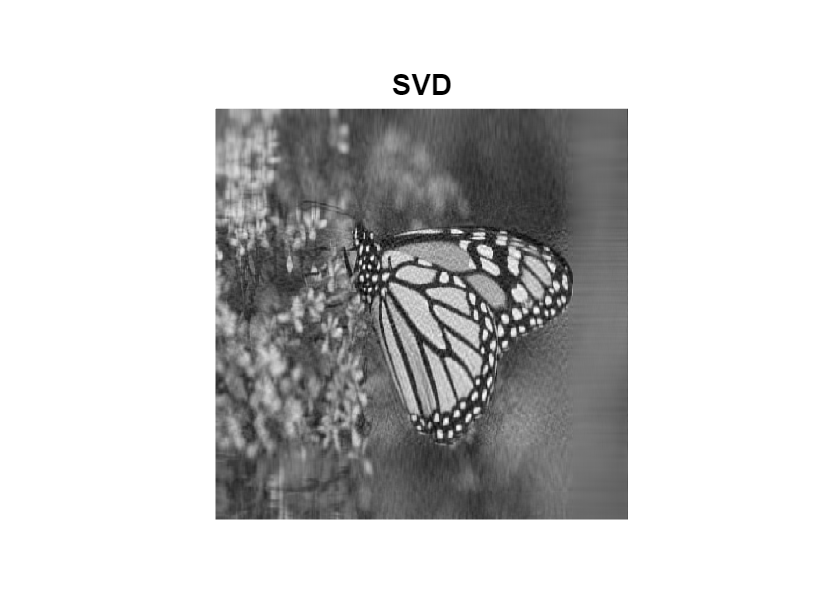


%nexttile
imagesc(svd_img)
colormap("gray")
axis('off')
title("SVD")
pbaspect([1 1 1])
clim([0,255])

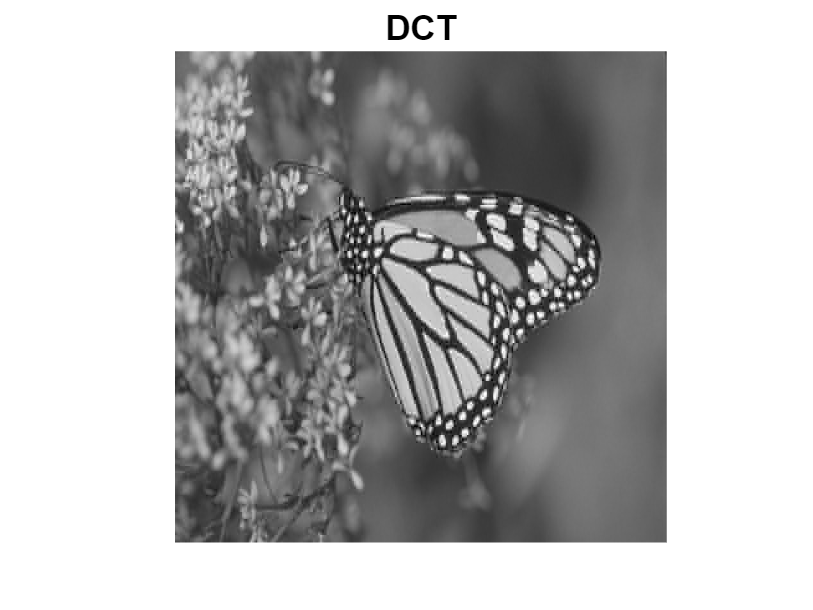


%nexttile
imagesc(dct_img)
colormap("gray")
axis('off')
title("DCT")
pbaspect([1 1 1])
clim([0,255])

copygraphics(gcf)

function [MSE, TIME, NZV, OUTPUT] = compression_test(method, image, parameter)
    tic;
    [OUTPUT, NZV] = method(image, parameter);
    TIME = toc;
    
    
    MSE = mean((double(image) - double(OUTPUT)).^2,'all');
end